# **Serial - Onboard RS-232 Loopback**

This example shows you how to do a loopback test over RS-232 with the onboard serial ports of a Speedgoat real-time target machine. It features two different encoding and decoding options for the data and explains the standard and legacy input and output options. The Simulink model can be configured for the serial interfaces from the [Serial Onboard ](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_serial_onboard)family.

The example implements a loopback by sending the serial messages from port 1 to port 2 by using the [Protocol Encoder](https://www.mathworks.com/help/slrealtime/io_ref/protocolencoder.html) and [Protocol Decoder](https://www.mathworks.com/help/slrealtime/io_ref/protocoldecoder.html) blocks and from port 2 to port 1 by using the [ASCII Encode](https://mathworks.com/help/slrealtime/io_ref/asciiencode.html) and the [ASCII Decode](https://mathworks.com/help/slrealtime/io_ref/asciidecode.html) blocks.

The following concepts are featured:

- Configuring the [Serial Onboard](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_serial_onboard) driver blocks for the standard and for the legacy input and output options

- Setting the correct FIFO size for the transmit and receive buffer in the [Serial Onboard - Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_serial_onboard_setup) block, as well as for the data stream buffer with the [FIFO Write](https://www.mathworks.com/help/slrealtime/io_ref/fifowrite.html) block

- Encoding and decoding of Simulink signals into or from a uint8 byte stream by using the [Protocol Encoder](https://www.mathworks.com/help/slrealtime/io_ref/protocolencoder.html) and [Protocol Decoder](https://www.mathworks.com/help/slrealtime/io_ref/protocoldecoder.html) blocks

- Encoding Simulink signals into an ASCII data stream by using an [ASCII Encode](https://mathworks.com/help/slrealtime/io_ref/asciiencode.html) block

- Decoding ASCII data to Simulink signals by using [ASCII Decode](https://mathworks.com/help/slrealtime/io_ref/asciidecode.html) blocks

- Extracting sub messages based on a header string with the [FIFO Read HDRS](https://mathworks.com/help/slrealtime/io_ref/fiforeadhdrs.html) block

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with two onboard serial ports       

- D-Sub 9 crossover/null modem cable 

### Test Setup

In this example, data is sent from the Serial port 1 to port 2 and from the Serial port 2 to port 1. For this, the two serial ports are connected with a D-Sub 9 crossover/null modem cable, which connects the Tx and the Rx pins. 

For the detailed pin mapping of the D-Sub 9 connectors, please refer to [Serial Onboard Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_serial_onboard_pin_mapping)

## Open the Simulink Model

 
% Open Simulink model
modelName = 'sgMdl_Serial_Onboard_RS232Loopback';
open_system(modelName);

### Model Description

#### Onboard Serial Setup

Please note that by default this Simulink model is configured to be used with a Performance real-time target machine. To change to another target, simply change the **Machine Type** in all the serial blocks. Note that the number of available serial interfaces varies across Speedgoat target machines.

This example demonstrates the use of two RS232 serial channels, which are enabled and configured through the [Serial Onboard - Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_serial_onboard_setup) block. Here, you will set general serial parameters such as baud rate and parity. Crucially, you must also configure the Transmit and Receive FIFO (First-In, First-Out) buffer sizes.

The appropriate FIFO size depends on several factors: the baud rate, the size of your serial messages, and the sample time of your [Serial Onboard - Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_serial_onboard_read) and [Serial Onboard - Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_serial_onboard_write) blocks. It is essential to ensure that the FIFO buffers are sufficiently large to store at least two complete messages. This prevents data loss in scenarios where a message transmission is interrupted or not fully completed before a new message is written to the buffer.

#### Protocol Encoder/Decoder

In the upper part of the model, the [Protocol Encoder](https://www.mathworks.com/help/slrealtime/io_ref/protocolencoder.html) and the [Protocol Decoder](https://www.mathworks.com/help/slrealtime/io_ref/protocoldecoder.html) blocks are used, enabling the conversion of Simulink signals into a `uint8` byte stream according to a user-defined packet structure and data type configuration. This encoded byte stream is then transmitted over Serial Port 1 using the [Serial Onboard - Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_serial_onboard_write) block. For loopback testing, the [Serial Onboard Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_serial_onboard_read) block on Serial Port 2 receives the transmitted data.

The size of the resulting byte stream is directly influenced by the number and data types of the configured packet fields. An optional checksum can further increase the stream's length. The [Serial Onboard - Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_serial_onboard_write) block requires two inputs: the data payload and the number of bytes to transmit. The maximum length of the data input is determined by the **Transmit Software FIFO Size** within the [Serial Onboard - Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_serial_onboard_setup) block. To ensure the byte stream generated by the Protocol Encoder block matches this required length, a Ground block and a Mux block are used. This process effectively pads the byte stream with zero-valued bytes, filling any remaining space. The [Width](https://www.mathworks.com/help/simulink/slref/width.html) block is used to accurately determine the number of bytes in the padded stream, providing the necessary value for the [Serial Onboard - Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_serial_onboard_write) block's **Count** input.

Upon receiving data, the [Serial Onboard Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_serial_onboard_read) block provides the received byte stream and the corresponding byte count through its **Data** and **Count** output ports. These outputs serve as inputs to the [Protocol Decoder](https://www.mathworks.com/help/slrealtime/io_ref/protocoldecoder.html) block. The Protocol Decoder's configuration mirrors that of the Protocol Encoder, ensuring accurate decoding. The resulting decoded signals are presented as individual output ports. Furthermore, the **IsNew** signal is provided to indicate the successful reception of a complete message within the current sample step.

#### ASCII-Coded and Legacy Mode

In the lower part of the model, two sine wave signals and one pulse signal are encoded to an ASCII data stream and transmitted by Serial port 2 to Serial port 1, using the **Legacy Mode.** The legacy mode is used as it supports the same data type as the [ASCII Encode](https://mathworks.com/help/slrealtime/io_ref/asciiencode.html) block outputs, which is a NULL-terminated character string with a delimiter after the ASCII-encoded variable. Consequently, it is easy to extract the encoded variable and only complete messages are decoded.

On the receiving side, the ASCII data stream from port 1 is buffered and then decoded to extract the original signals. Buffering received data with the [FIFO Write](https://www.mathworks.com/help/slrealtime/io_ref/fifowrite.html) block is required, as a partially complete message might be read when the [Serial Onboard - Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_serial_onboard_read) block is executed. To ensure compatibility with the [ASCII Decode](https://mathworks.com/help/slrealtime/io_ref/asciidecode.html) blocks' input port data type, the receive loopback is configured to use the NULL-terminated character string, which is sent from port 2.

To prevent data loss in case of an overflow, the size of the buffer is set to double the size of the receive FIFO configured in the [Serial Onboard - Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_serial_onboard_setup) block. The [FIFO Read HDRS](https://mathworks.com/help/slrealtime/io_ref/fiforeadhdrs.html) block parses the data stream received for the specified headers ('`sine1`', '`pulse`', '`sine2`') and the termination ('`\r\n`' = [13 10]) in order to extract a complete message containing the three sub messages. The maximum read size is set to the same size as the buffer of the [FIFO Write](https://www.mathworks.com/help/slrealtime/io_ref/fifowrite.html) block. Once a complete message is available in the buffer, the message is split up into the three different sub messages and then decoded by the [ASCII Decode](https://mathworks.com/help/slrealtime/io_ref/asciidecode.html) blocks. These blocks convert the ASCII strings into double values for further processing in the model. 

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### **Possible Issues**

A problem has been encountered with the FIFO Write block used in the legacy configuration with the ASCII workflow. The error PopUp "FIFO overflow: RX Ch1 overflow" may appear.

The referenced FIFO is not linked to the Serial FIFO of the target or the module. In the ASCII workflow, the data is written to a dedicated FIFO and immediately read back so it can be formatted correctly for ASCII decoding. The FIFO Write writes to the FIFO, and the FIFO Read reads the FIFO when it detects the delimiter. 

If, for some reason, the messages are not sent correctly, the delimiter may not be transmitted In this case, the FIFO is filled but not emptied, eventually overflowing. One of the causes of the incorrect transmission is unreliable wiring of the terminal board. This ASCII workflow is not tolerant of wiring issues.

To resolve this issue there are three solutions:

- Check the wiring.

- Uncheck the "Read to delimiter" option in the FIFO Read block. (This option is usually suggested to have checked in the ASCII workflow.)

- Do not use the ASCII workflow with the FIFO blocks.

### Check the Results

To check if the loopback is working as expected and the variables are correctly encoded from the data stream, open the Simulink scopes. On each scope, three signals must be displayed:

#### Scope Ch1

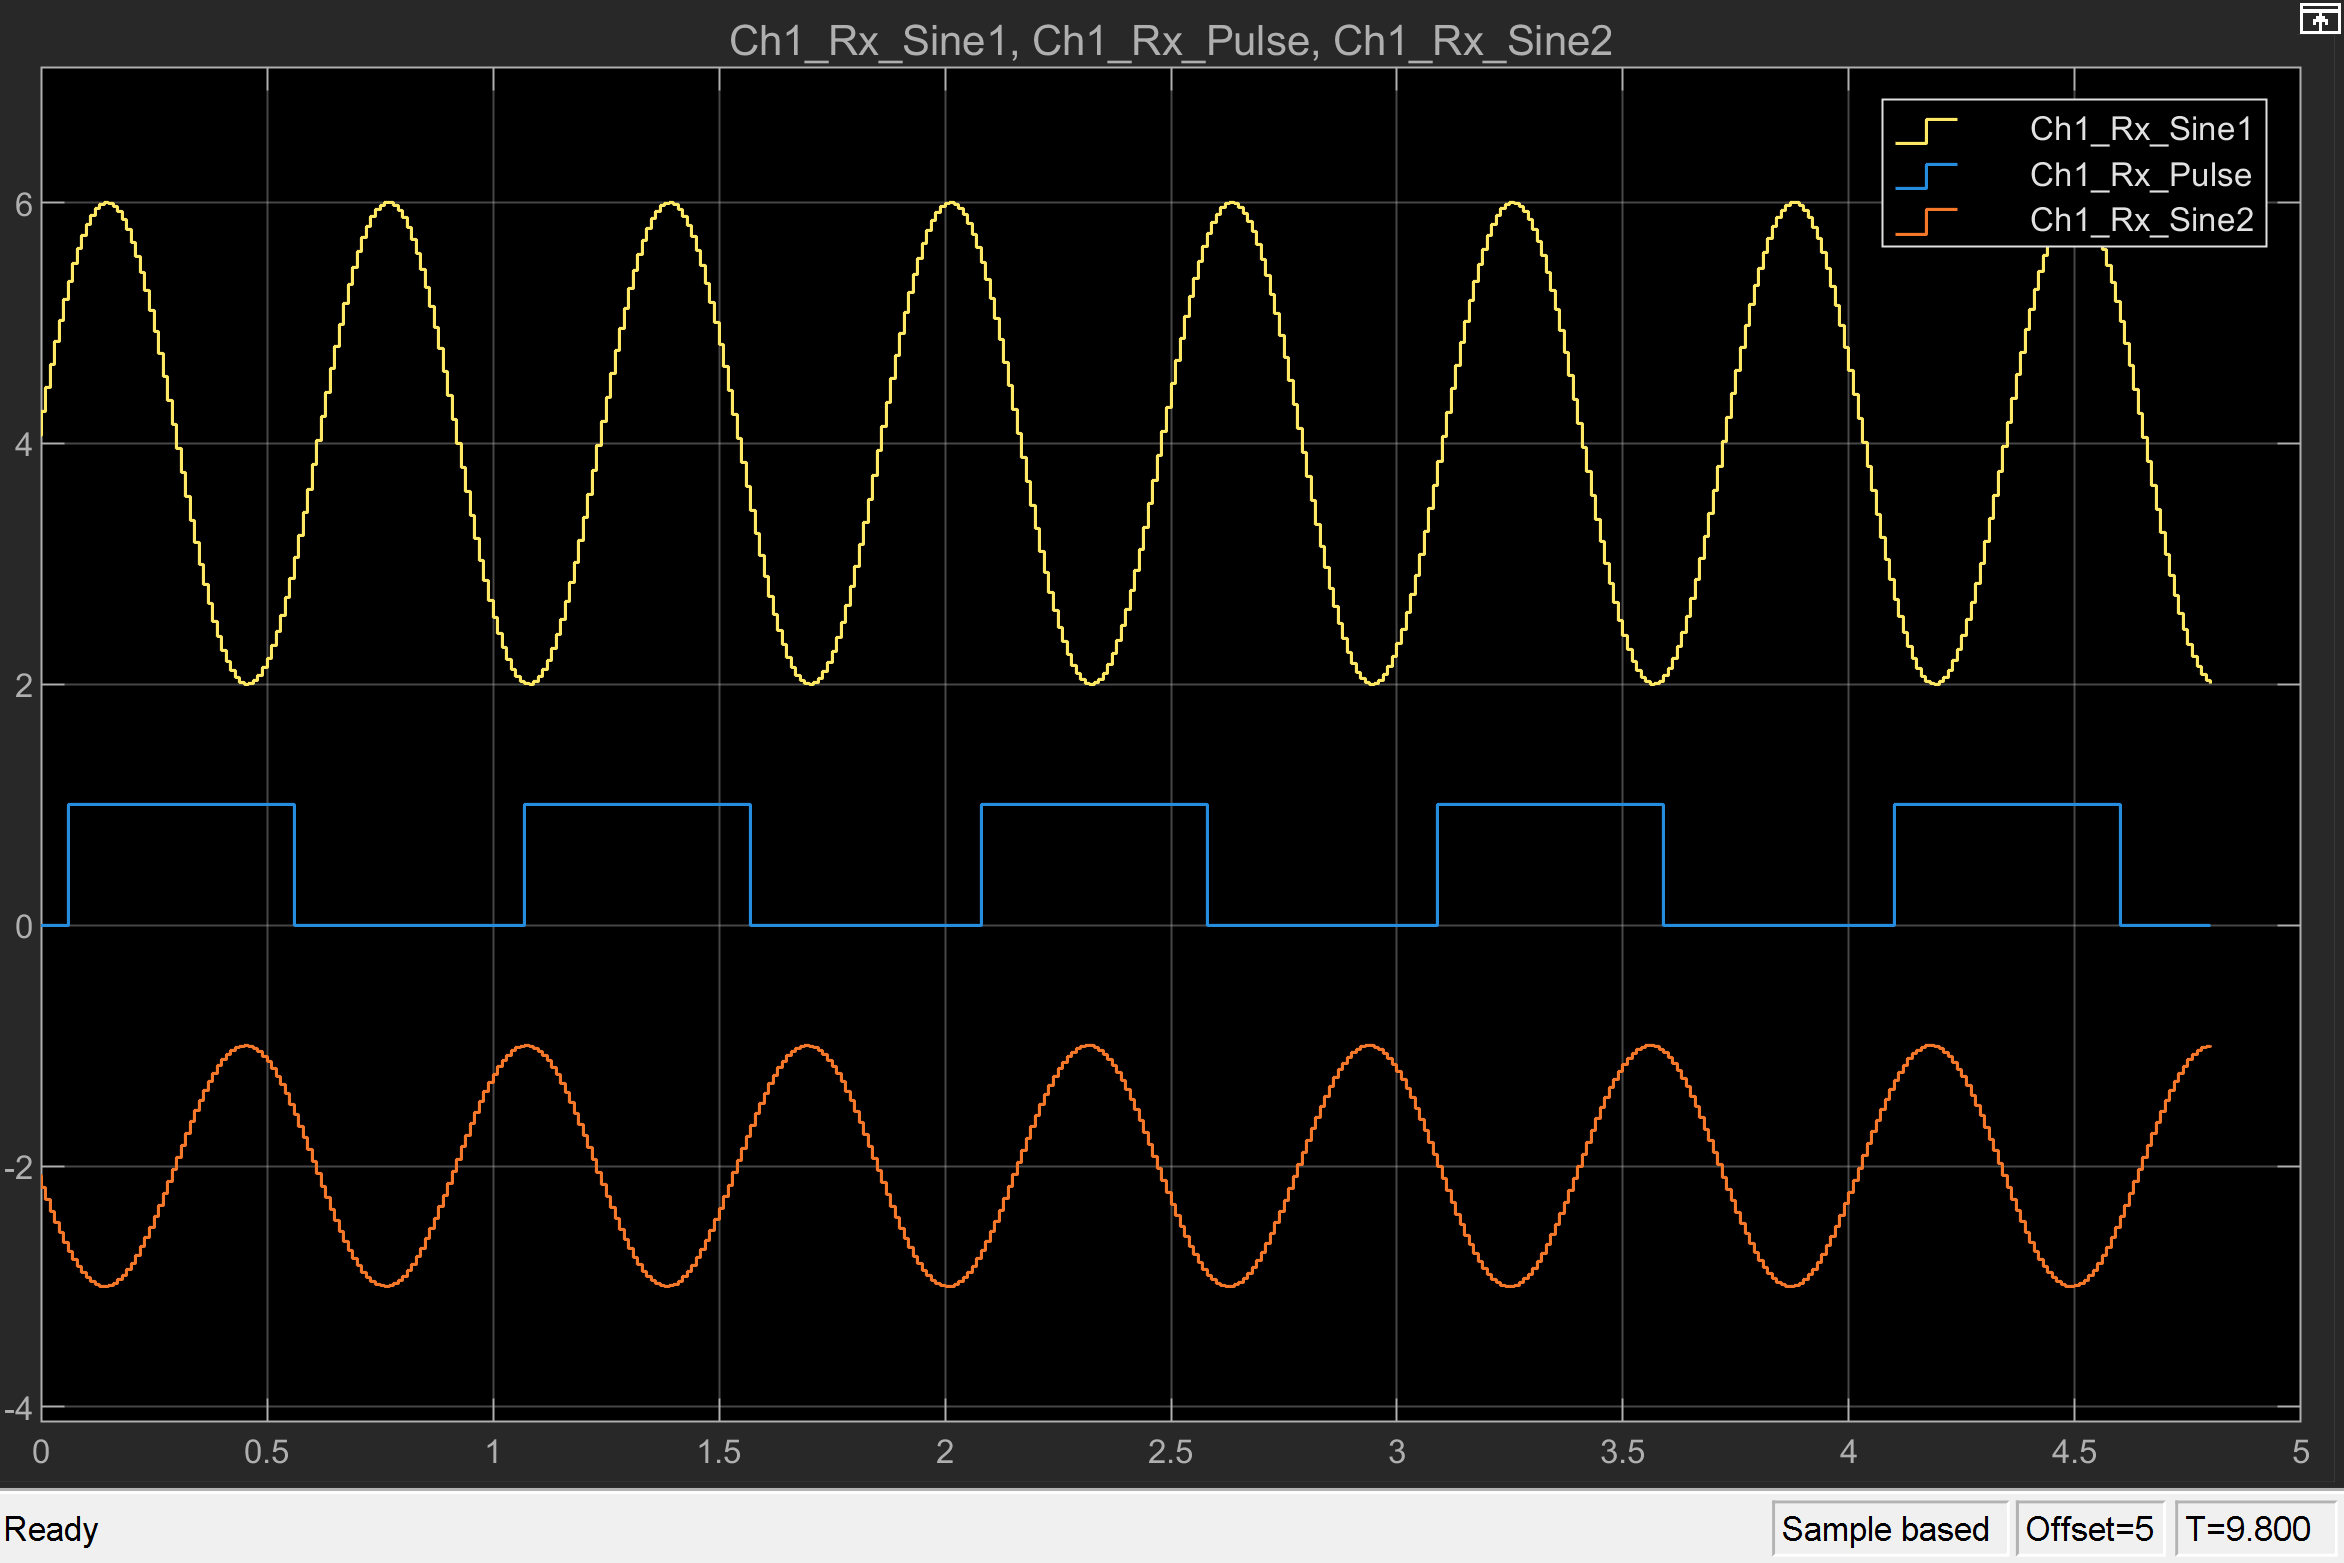

#### Scope Ch2

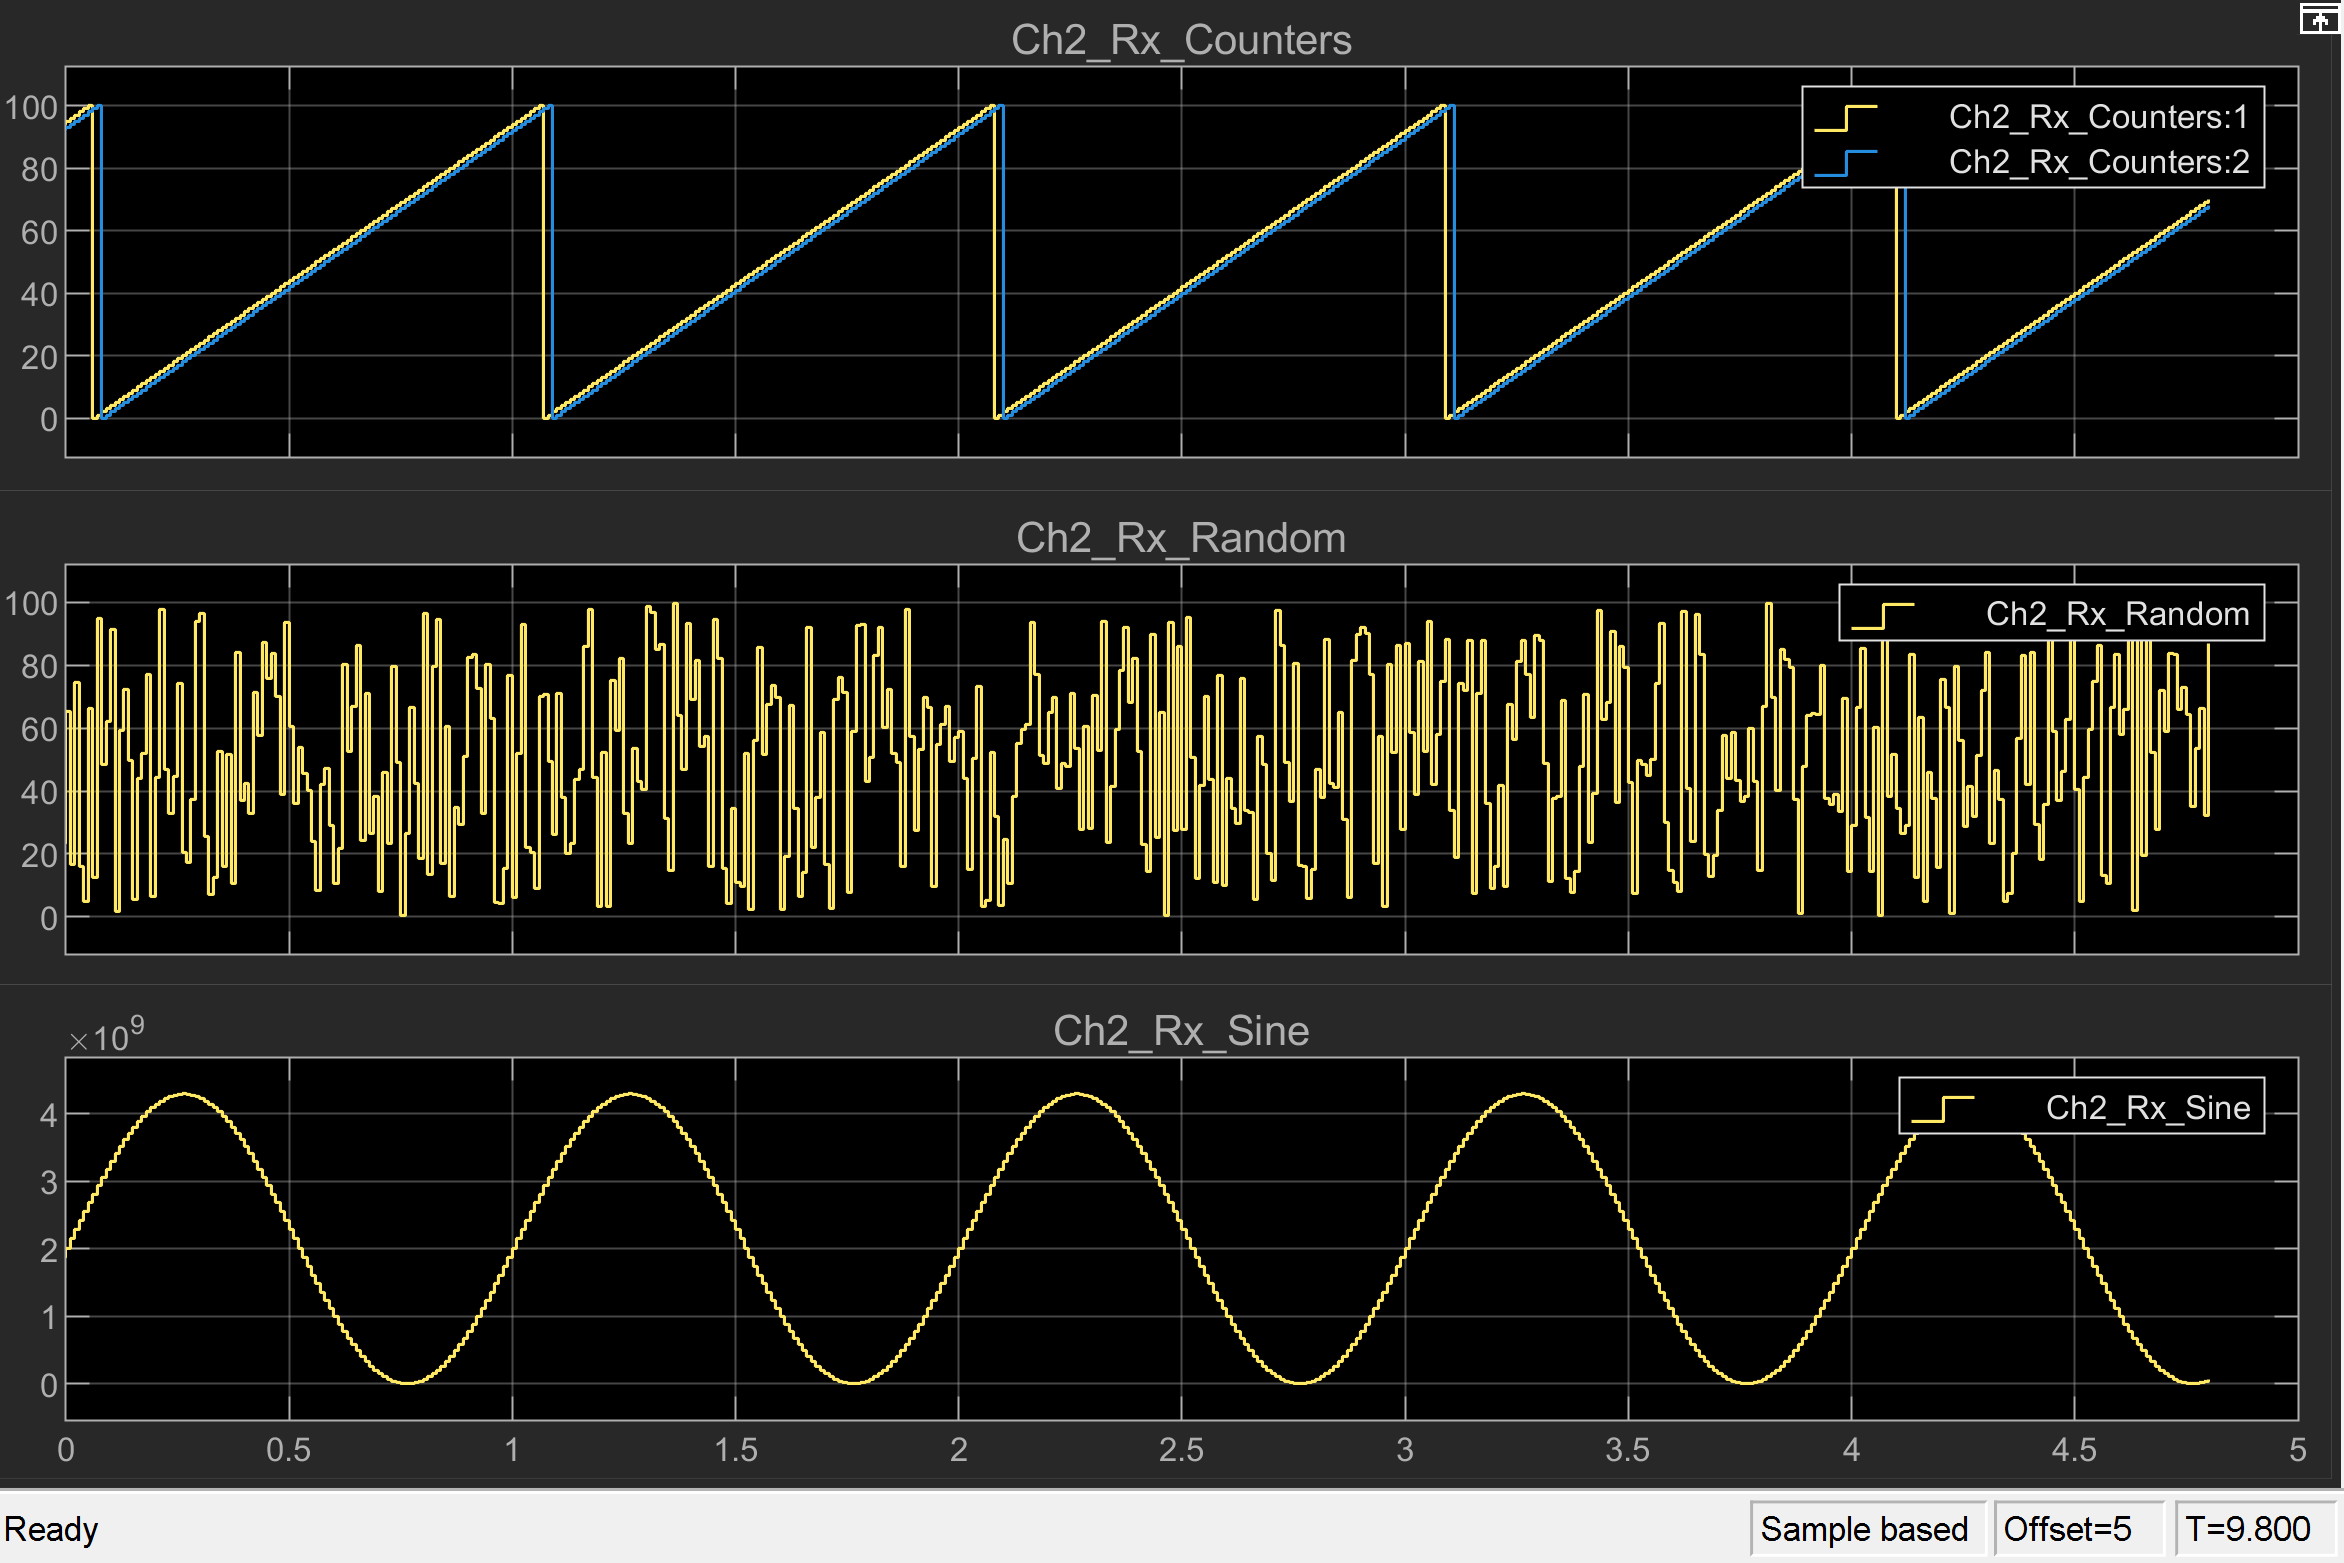

## Additional References

- [Serial Onboard documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_serial_onboard)